# Display Spectrum of a Streaming Signal

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

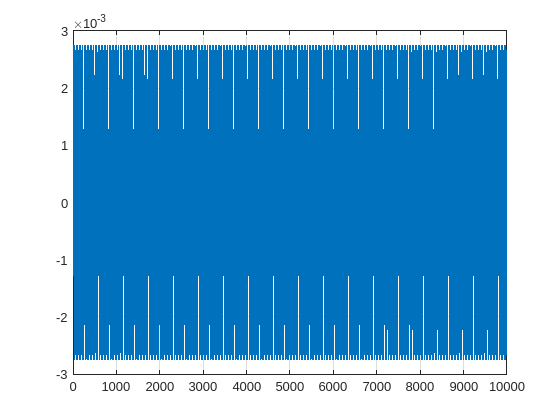

load ./data/monitoredfan.mat
src = dsp.SignalSource(monitoredfan,10000);
data = src();
plot(data)
grid on

## Task 1

To display the spectrum of a streaming signal, you can use the Spectrum Analyzer System object:

`a` `=` `spectrumAnalyzer`

analyzer = spectrumAnalyzer("SampleRate",fs,"PlotAsTwoSidedSpectrum",false,"Method","Welch")

analyzer =   spectrumAnalyzer with properties:

               InputDomain: 'time'
              SpectrumType: 'power'
                  ViewType: 'spectrum'
                SampleRate: 2400
                    Method: 'welch'
    PlotAsTwoSidedSpectrum: 0
            FrequencyScale: 'linear'
                  PlotType: 'line'
               AxesScaling: 'auto'

  Show all properties


## Task 2

analyzer = spectrumAnalyzer("SampleRate",fs,"PlotAsTwoSidedSpectrum",false)

analyzer =   spectrumAnalyzer with properties:

               InputDomain: 'time'
              SpectrumType: 'power'
                  ViewType: 'spectrum'
                SampleRate: 2400
                    Method: 'filter-bank'
    PlotAsTwoSidedSpectrum: 0
            FrequencyScale: 'linear'
                  PlotType: 'line'
               AxesScaling: 'auto'

  Show all properties


## Task 3

Now you can use the System object that you just created like a function:

`a` `=` `spectrumAnalyzer`

`a``(``frame1``)`

Once you do, Spectrum Analyzer will display as a pop-up. If you need to edit the script, close Spectrum Analyzer first.

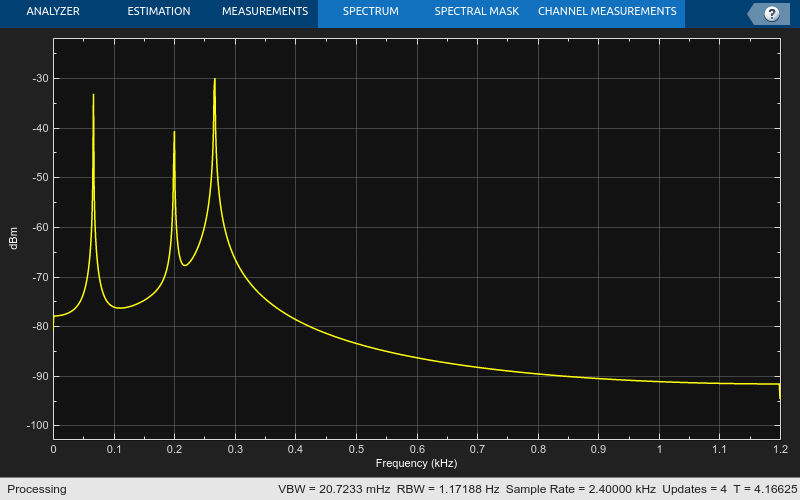

analyzer(data)